# Raman Nath Regime


%% Initialization 

units % load some common physical constants
m_Li6mol = 2*m_Li6;
aLi_12 = 982*a0;
add_Li = aLi_12*0.6;

omegax = 16*pi*2; % trap frequencies 
omegay = 74*pi*2;
omegaz = 68*pi*2;

% scale parameters
tscale = 1/(omegax); % time scale
rscale = sqrt(hbar/m_Li6mol/omegax); % spatial scale

% Lattice parameters defination
Wavelength = 1064*10^-9;
CrossingAngle = 15/180*pi; % cross angle for two ODT beams
D = Wavelength/(2*sin(CrossingAngle/2)); % Lattice period 4 micons
Erecoil = hbar^2*(pi/D)^2/(2*m_Li6mol); % recoil energy 250 Hz.

LatticePotential = 500; % lattice depth in unit of recoil energy
V = @(X,Y,Z) 0.5*(X.^2 + (omegay/omegax* Y).^2); % function representing the external potential (must have 3 arguments)


xmax = 25*D/rscale; %  grid boundaries [-xmax,xmax]
N = 1000; % number of grid points for coordinate grid

try
    x = gpuArray.linspace(-xmax,xmax,N);
    grid = grid2d(x);
catch
    grid = grid2d(xmax,N,xmax,N); % create a two-dimensional NxN grid object
end

task = GPEtask(grid,V); % initialize the GPE solver
task.Ntotal = 3000; % wave function normalization (total number of atoms)


task.Xscale = rscale;
task.Tscale = tscale;
task.LatticeConstant = D;


%% Stationary state calculation

% phi = task.groundstate_itp(tstep,acc,'tf'); % phi will contain calculated stationary state
[phi,mu,R] = task.groundstate_tf_harmonic(add_Li,omegax,omegay,omegaz);
task.g = 4*pi*add_Li/rscale/sqrt(2*pi/sqrt(omegaz*omegay)*omegax); % nonlinear interaction constant


%% switch on lattice for Deltat
Deltat = 20*10^-6/tscale; % total duration for simulation; (20 mico-seconds)
tstep = 20*10^-9/tscale; % time step for calculation; (20 ns)
steps_int = 10;  % number of intenal steps. (should be larger than 10 task.n_recalc)

task.init_state = phi;
task.show_image = 0; % show the solution on every precessing step


NmaxP = 9; % maximum mode of momentum to be analyzed

% function representing the external potential (must have 3 arguments)
Vlattice = @(X,Y,Z) LatticePotential*Erecoil/(hbar*omegax)*cos((pi/D)*X*rscale).^2; 
task.UpdatePotential(Vlattice);
% task.history.MomentumDensity = [];
task.user_callback = @(x)task.FFTanalysis2D(1,NmaxP);
steps_ext = task.current_iter + Deltat/tstep/steps_int;

Split-step: iter - 1, mu - 3914.633, calc. time - 1.302 sec.; 0 mode Proportion: 0.997
Split-step: iter - 2, mu - 3914.633, calc. time - 1.917 sec.; 0 mode Proportion: 0.988
Split-step: iter - 3, mu - 3914.633, calc. time - 2.664 sec.; 0 mode Proportion: 0.972
Split-step: iter - 4, mu - 3914.633, calc. time - 3.402 sec.; 0 mode Proportion: 0.951
Split-step: iter - 5, mu - 3914.633, calc. time - 4.003 sec.; 0 mode Proportion: 0.925
Split-step: iter - 6, mu - 3914.633, calc. time - 4.641 sec.; 0 mode Proportion: 0.894
Split-step: iter - 7, mu - 3914.633, calc. time - 5.401 sec.; 0 mode Proportion: 0.857
Split-step: iter - 8, mu - 3914.633, calc. time - 6.202 sec.; 0 mode Proportion: 0.817
Split-step: iter - 9, mu - 3914.633, calc. time - 7.000 sec.; 0 mode Proportion: 0.773
Split-step: iter - 10, mu - 3914.633, calc. time - 7.599 sec.; 0 mode Proportion: 0.726
Split-step: iter - 11, mu - 3914.633, calc. time - 8.200 sec.; 0 mode Proportion: 0.676
Split-step: iter - 12, mu - 3914.633, cal

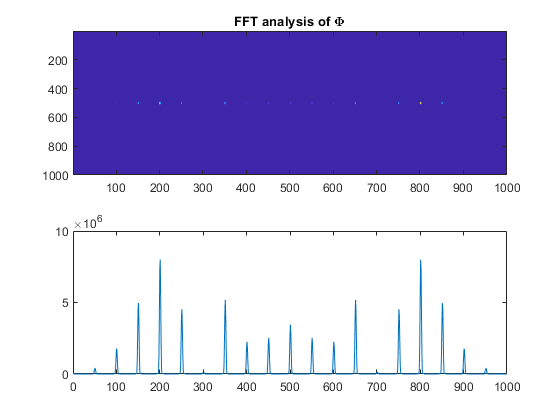

Split-step: iter - 99, mu - 3919.417, calc. time - 69.423 sec.; 0 mode Proportion: 0.0547



% start simulation
task.solve_split(tstep,steps_int,steps_ext); % run the calculation

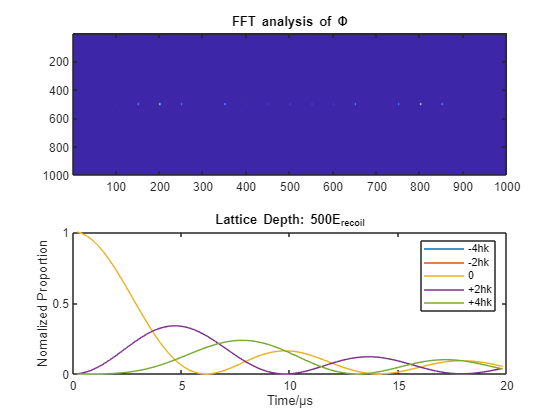


trange = (1:steps_ext)*tstep*steps_int*tscale;
MomentumDensity = Get_momentumDesity_2D( ...
    task.history.MomentumDensity,NmaxP+1,1:NmaxP*2+1);
MomentumDensity = MomentumDensity./max(MomentumDensity(:));
plot(trange*10^6, MomentumDensity(:,NmaxP-1:NmaxP+3)')
xlabel('Time/\mus')
ylabel("Nomalized Proportion")
title(['Lattice Depth: ',num2str(LatticePotential),'E_{recoil}'])
legend('-4hk','-2hk','0','+2hk','+4hk')

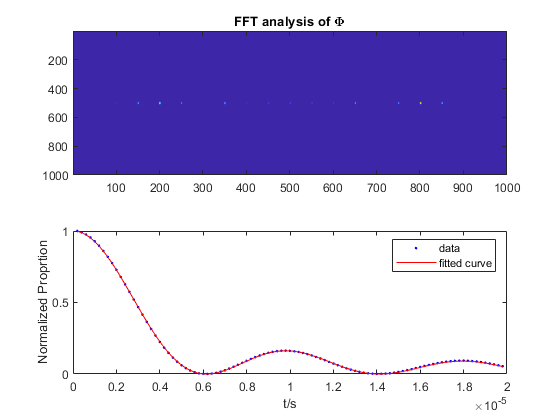

Tcoeffienct = 3.9076e+05


Tcoeffienct = BesselFit(trange,MomentumDensity(:,NmaxP+1)',0)


Tcoef_theory = LatticePotential*Erecoil/2/hbar

Tcoef_theory = 3.9204e+05

 Raman-Nath regime?

For Raman-Nath regime


$$t_{\max } \frac{\sqrt{E_r U_0 }}{\hbar }<1$$


Deltat*tscale * sqrt(LatticePotential)*Erecoil/hbar

ans = 0.7013